## Задание 2. Линейные фильтры. Специальный фильтр

Рассмотрите такой же сигнал 


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


**Специальный фильтр**

$W_2 \left(p\right)=\frac{T_1^2 p^2 +2T_1 p+1}{T_2 T_3 p^2 +\left(T_2 +T_3 \right)p+1}$ - так выглядит наш фильтр

где $T>0$ - постоянная времени, $p$ - оператор дифференцирования, по просту - точечная производная

Берём функцию g, что... 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\textrm{else}
\end{array}\right.$$


*Задаём параметры линейный пространств*

dt  = 0.01;
t = -20:dt:20;

V_min = -1500; V_max = 1500;
n = 4001;
freqs = linspace(V_min, V_max, n);


#### Испытание 1

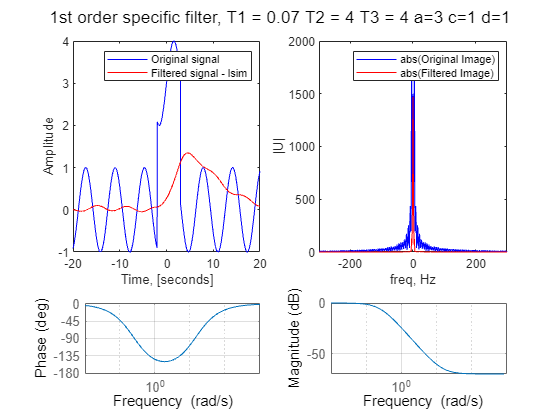

T1 = 0.07; T2 = 4; T3 = 4;
a = 3; b = 0; c = 1; d = 1;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 2

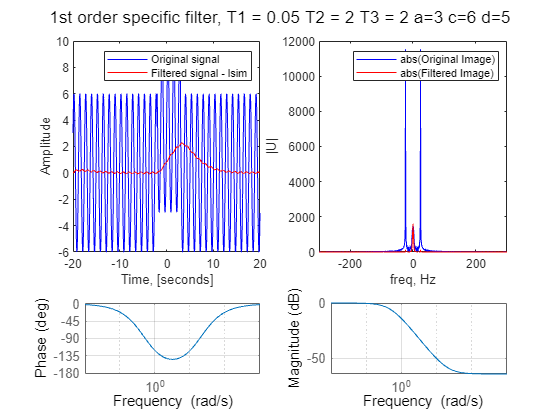

T1 = 0.05; T2 = 2; T3 = 2;
a = 3; b = 0; c = 6; d = 5;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 2

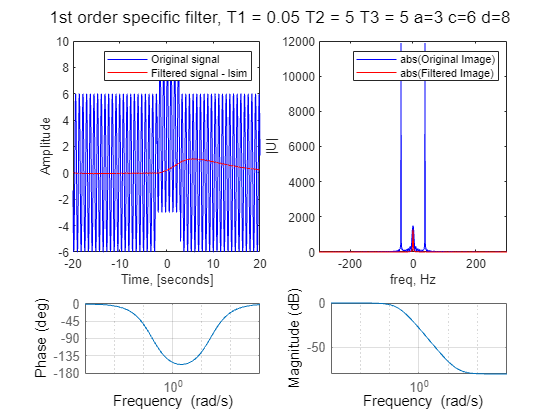

T1 = 0.05; T2 = 5; T3 = 5;
a = 3; b = 0; c = 6; d = 8;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 3

% T1 = 0.1; T2 = 0.5; T3 = 0.5;
% a = 3; b = 0; c = 4; d = 8;
% t1 = -2; t2=3; 
% u = noisy(t, t1, t2, a, b, c, d);
% filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 4

% T1 = 0.04; T2 = 0.5; T3 = 0.5;
% a = 3; b = 0; c = 6; d = 6;
% t1 = -2; t2=3; 
% u = noisy(t, t1, t2, a, b, c, d);
% filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 5

% T1 = 5; T2 = 8; T3 = 8;
% a = 3; b = 0; c = 5; d = 4;
% t1 = -2; t2=3; 
% u = noisy(t, t1, t2, a, b, c, d);
% filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

#### Испытание 6

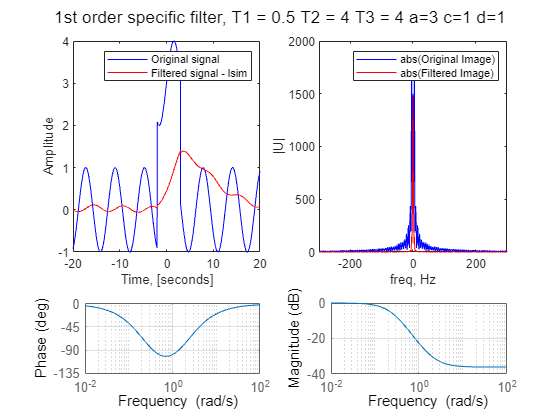

T1 = 0.5; T2 = 4; T3 = 4;
a = 3; b = 0; c = 1; d = 1;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter2_test(t, freqs,u, T1,T2,T3, a, b, c, d)

Лучшие результаты показало второе испытание, похоже равенство $T_2 =T_3$ - даёт очень хорошие результаты... Поэтому расширили эту категорию испытанийЮ добавив несколько ситуаций с разными параметрами $c,d$

## Все функции, используемые в скрипте

**Вспомогательная функция "пошумим"**

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end


**Функция "пошумим"**

function y = noisy(t, t1, t2, a, b, c, d)
    y = g(t, a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
end

** Специальный фильтр - проведение одного испытания**

function filter2_test(t, freqs,u, T1, T2, T3, a, b, c, d)
%     Задаём параметры для фильтра
%     b = ;
%     a = ;
    % Создаем фильтр первого порядка (передаточную функцию Лапласа)
    W3 = tf([T1^2 2*T1 1], [T2*T3 T2+T3 1]);

    p = tf('p');
    W1 = ((T1*p+1)^2)/((T2*p+1)*(T3*p+1));

    
    y = lsim(W1,u,t);

    % Строим графики
    figure( randi([1 3000],1) )
    sgtitle("1st order specific filter, T1 = " + T1 + " T2 = " + T2 + " T3 = " + T3 + " a=" + a + " c=" +c+ " d=" + d)
    subplot(3, 2, [1,3])
    plot(t, u, 'b', t, y, 'r')
    xlabel('Time, [seconds]')
    ylabel('Amplitude')
    legend('Original signal', 'Filtered signal - lsim')
    
    subplot(3, 2, [2,4])
    plot(freqs, fftshift(abs(fft(u))), 'b', freqs, fftshift(abs(fft(y))), 'r')
    xlabel('freq, Hz')
    ylabel('|U|')
    xlim([-300, 300])
    legend('abs(Original Image)', 'abs(Filtered Image)')
    % Вычисляем АЧХ и ФЧХ
    % Отделяем АЧХ от ФЧХ
   
    subplot(3,2,5);
    h1 = bodeplot(W1);
    % Отключаем один из подграфиков, а также делаем пустой заголовок
    setoptions(h1, 'MagVisible','off', 'Title', struct('String',''));
    grid on
    subplot(3,2,6);
    h2 = bodeplot(W1);
    setoptions(h2, 'PhaseVisible','off','Title', struct('String',''));
    grid on
    hold off;    

    save_file(T1, T2, T3, a, b, c, d)
end

**Save file in the folder**

function save_file(T1, T2, T3, a, b, c, d)
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
    T1_str = strrep(sprintf('%0.2f', T1), '.', '_');
    T2_str = strrep(sprintf('%0.2f', T2), '.', '_');
    T3_str = strrep(sprintf('%0.2f', T3), '.', '_');
    

    Name = "test_specific_filter=" + a+"_b="+b+"_c="+c+"_d="+d +"_T1="+ T1_str +"_T2="+ T2_str +"_T3="+ T3_str;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');

end